Teste SM_mola.massa sem amortecimento

syms u(t) v(t)


f =@(t,u,v) v;
g =@(t,u,v) -sin(u)-0.3*v;
a = 0;
b = 15;
n = 100;
u0 = pi/2;
v0 = 0;


eqns = [diff(u,t,1)==v,diff(v,t,1)==-sin(u)-0.3*v] ;
ci = [u(a)==u0,v(a)==v0];

[sExataU,~]= dsolve(eqns,ci); %derivada do v em ordem a t == 

h=@(t) eval(vectorize(char(sExataU)));

[t,uEuler,~] = NEulerSED(f,g,a,b,n,u0,v0);
%[~,uEulerMelh,~] = NEulerMelhSED(f,g,a,b,n,u0,v0);
[~,uRK2,~] = NRK2SED(f,g,a,b,n,u0,v0);
[~,uRK4,~] = NRK4SED(f,g,a,b,n,u0,v0);

uExata = h(t);

erroEuler = abs(uExata-uEuler);
erroRK2 = abs(uExata-uRK2);

array2table([t.',uExata.',uEuler.',uRK2.',erroEuler.',erroRK2.'],...
    "VariableNames",{'t','Exata','Euler','RK2','erroEuler','erroRK2'})

ans = 101×6 table
     t       Exata        Euler         RK2       erroEuler     erroRK2 
    ____    ________    _________    _________    _________    _________

       0      1.5708       1.5708       1.5708            0            0
    0.15      1.5615       1.5708       1.5595    0.0093261    0.0019239
     0.3       1.534       1.5483       1.5268     0.014255    0.0072429
    0.45      1.4893       1.5043       1.4735     0.015003     0.015792
     0.6       1.428       1.4398       1.4007     0.011782     0.027351
    0.75      1.3509       1.3558       1.3093    0.0048291     0.041581
     0.9      1.2587       1.2532       1.2008    0.0055274     0.057939
    1.05       1.152       1.1332       1.0764     0.018794     0.075597
     1.2      1.0315      0.99732      0.93819 

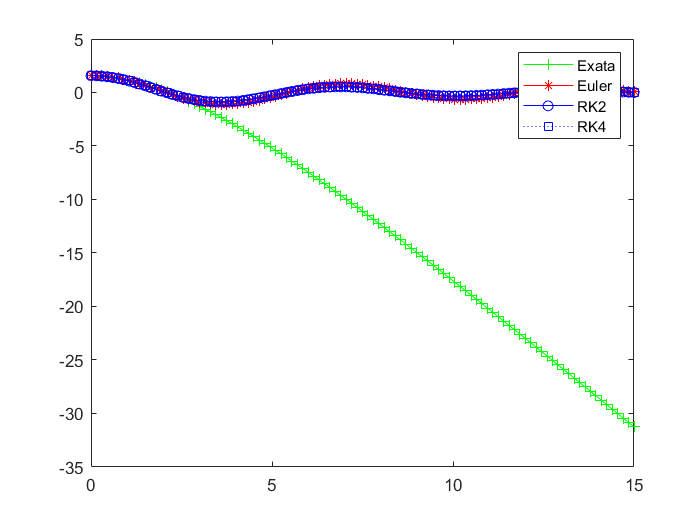



plot(t,uExata,"-g+")
hold on
plot(t,uEuler,"-r*")
plot(t,uRK2,"-bo")
plot(t,uRK4,":bs")
hold off
legend("Exata","Euler","RK2","RK4")

Fórmulas para 1 equação diferencial:

Resolvem:    dy/dt = f(t,y)